# Example: Green's Functions in 1D Acoustics

This live-script features the following:

- 1D example

- generates and validates the Green's function for this problem

Here we consider acoustic pressure data 


$$d = \{ p(x_r,t), \; 0\le t \le T\}$$
 

for a single ***receiver location*** $x_r$, where the pressure field $p$ satisfies the 1D acoustic equations:


$$\frac{\partial p}{\partial t} + \kappa \frac{\partial v}{\partial x} = w(t)\delta(x-x_c)$$



$$\frac{\partial v}{\partial t} + \beta \frac{\partial p}{\partial x} = 0$$


Given source time function $w(t)$, the resulting pressure data can be generated by using a Green's function,


$$p(x_r,t) = G_p(x_r,t)* w(t)$$


where $*$ denotes time convolution and $G_p$ is the pressure field Green's function satisfying


$$\frac{\partial G_p}{\partial t} + \kappa \frac{\partial G_v}{\partial x} = \delta(t)\delta(x-x_c)$$



$$\frac{\partial G_v}{\delta t} + \beta \frac{\partial G_p}{\partial x} = 0$$


 with the same initial and boundary conditions as in the original problem.

## Initial set up

clear

t_final = 1;
domain_t = [0,t_final];
domain_x = [0,1];

% Initial conditions
p0 = @(x) zeros(size(x));
v0 = @(x) zeros(size(x));

% Initializing PML
pml = PML1D(WidthLeft=0.2,WidthRight=0.2);

% Single point receiver
x_rcv = 0.2;
gridSp_rcv = GridSpace1D(Grid1D(domain_x,x_rcv));

% Continuous acoustic medium object function
% medium = AcousticMedium1D.layered( ...
%     BetaValues=[0.25,0.5,1], ...
%     KappaValues=[4,3,6], ...
%     Domain=domain_x, ...
%     RelativeWidths=[0.5,0.3,0.2]);
medium = AcousticMedium1D.constant(BetaValue=1,KappaValue=1);

## Computing pressure data directly

The time interval over which pressure data is computed is $[0,T]$.

As usual, we discretize the time domain by introducing a uniform grid with grid size $\Delta_t$ in such a way the required CFL condition is satisfied. We refer to the resulting time grid as the ***computational time grid***.

% Spatial computational grids and grid spaces
Nx=201;
grid_primal = Grid1DUnifPrimal(domain_x,Nx);
grid_dual   = Grid1DUnifDual(grid_primal);

gridSp_P = GridSpace1D(grid_primal); %grid space for pressure
gridSp_V = GridSpace1D(grid_dual);   %grid space for velocity
dx = gridSp_P.h;

% Sampling medium parameters to compute max wave speed 
[~,~,wspeed,cMax] = sampleMedium1D(gridSp_P,medium);

% Determining computational time grid size
CFL_factor = 0.8;
dt_cmp = CFL_factor*(6/7)*dx/cMax; %CFL condition for 2-4 FDM
Nt_cmp = ceil(diff(domain_t)/dt_cmp)+1;
dt_cmp = diff(domain_t)/(Nt_cmp-1); %recomputing to ensure time domain divisible by dt

% Computational time points
t_cmp = domain_t(1):dt_cmp:domain_t(2);

In practice, the pressure data is sampled/stored on a uniform time grid that is much coarser than the computational grid. This results in a time series vector for the pressure data, $\mathbf d\in\mathbb R^{K}$, with $d_i \approx p(x_r,t_i)$ for $i=0,1,...,K-1$ where $K$ is the total number of time points for the receiver. This new time grid is referred to as the ***receiver time grid***.

% Receiver time points
Nt_rcv = 101;
t_rcv  = linspace(domain_t(1),domain_t(2),Nt_rcv);
dt_rcv = diff(domain_t)/(Nt_rcv-1);

Here we initialize the monopole source for the 1D acoustic problem, $f(x,t) = w(t) \delta(x-x_c)$.

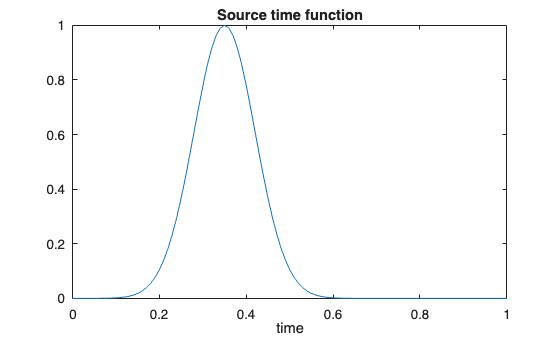

xc = 0.4;
tc = 0.35;
w = @(t) exp(-((t-tc)/0.1).^2);
monopole = MultipoleComponent1D(xc,0,TargetField="pressure");
mps = MultipoleSrcTerm1D(monopole,w);
appxOrder = 4;
source = mps.discretize(gridSp_P,gridSp_V,appxOrder);

figure
plot(t_rcv,w(t_rcv))
xlabel("time")
title("Source time function");

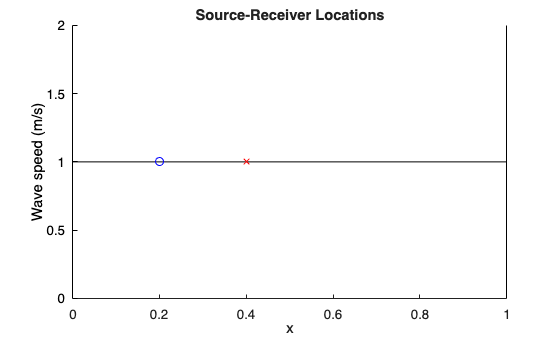

figure
plotAcqGeo(wspeed,mps,gridSp_rcv);
title("Source-Receiver Locations")

Initializing and running solver to compute acoustic data directly.

solver = AcousticSolver1D_PML( ...
    gridSp_P,   t_cmp, ...
    gridSp_rcv, t_rcv, ...
    medium, pml, ...
    SpatialOrder=4);

[P,~] = solver.solve(p0,v0,Source=source);
data = P.values(:);

## Computing pressure data for Green's function

For this test the spatial and time grids are the same as those used to compute the pressure data directly. In practice, more refined grids may be used for the Green's function computation.

% Spatial computational grids and grid spaces
NxG=Nx;
grid_primalG = Grid1DUnifPrimal(domain_x,NxG);
grid_dualG   = Grid1DUnifDual(grid_primalG);

gridSp_PG = GridSpace1D(grid_primalG); %grid space for pressure
gridSp_VG = GridSpace1D(grid_dualG);   %grid space for velocity
dxG = gridSp_PG.h;

% Sampling medium parameters to compute max wave speed 
[~,~,~,cMaxG] = sampleMedium1D(gridSp_PG,medium);

% Determining computational time grid size
CFL_factor = 0.8;
dt_cmpG = CFL_factor*(6/7)*dxG/cMaxG; %CFL condition for 2-4 FDM
Nt_cmpG = ceil(diff(domain_t)/dt_cmpG)+1;
dt_cmpG = diff(domain_t)/(Nt_cmpG-1); %recomputing to ensure time domain divisible by dt

In order to carry out convolutions with the Green's function $G_p$, we will need to extend the Green's function to be defined over $[-T,T]$.

Naive approach

Given that the Green's function is casual, that is, $G_p(x,t)=0$ for $t<0$, we could simply compute the Green's function over the same computational time grid as the pressure data, and simply pad by zeros the result time series. There is however an issue with this approach. When discretizing the time Dirac delta function $\delta(t)$, we end up with an acoustic source that is technically not causal. Let $\tilde \delta(t)$ represent said discretization. It turns out that $\tilde \delta(t) =0$ for $t<-\Delta_t$, where $\Delta_t$ is the computational time grid size.

Smarter approach

Since we know $\tilde \delta(t)=0$ for $t<-\Delta_t$, it suffices to set the computational domain to $[-\Delta_t, T]$, and pad the computed Green's function by zeros for the remaining time interval $[-T,-\Delta t)$.

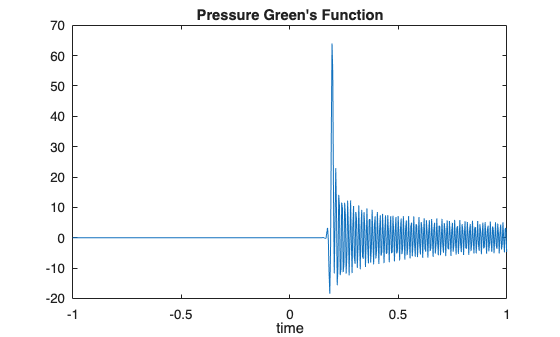

% Computational time points
t_cmpG = 0:dt_cmpG:t_final;
% Green solver times: one step before zero through t_final
t_cmpG_ext = (-1:Nt_cmpG-1)*dt_cmpG;

w_impulse = @(t) deltaTime(t,0,dt_cmpG);
mps_green = MultipoleSrcTerm1D(monopole,w_impulse);
source_green = mps_green.discretize(gridSp_PG,gridSp_VG,appxOrder);

% Initialize solver for direct data.
% Note that the output time grid is the same as the computational time
% grid.
solver_green = AcousticSolver1D_PML( ...
    gridSp_PG,  t_cmpG_ext, ...
    gridSp_rcv, t_cmpG_ext, ...
    medium, pml, ...
    SpatialOrder=4);

% Running solver
[P_green,~] = solver_green.solve(p0,v0,Source=source_green);
G_short = P_green.values(:);

% G_short begins at -dt_cmpG
data_green = [zeros(Nt_cmpG-2,1);G_short];

% Full Green grid from -t_final through t_final
t_ext = -t_final:dt_cmpG:t_final;

% Sanity checks
iZero = Nt_cmpG;
assert(numel(data_green) == numel(t_ext))
assert(abs(t_ext(iZero)) < 100*eps)

figure
plot(t_ext,data_green)
xlabel("time")
title("Pressure Green's Function")

## Computing pressure data via convolution

Here we implement the discretization of


$$p(x_r,t) = G_p(x_r,t)* w(t)$$


in two ways:

- by constructing the convolution matrix associated with our Green's function.

- computing convolution via FFT.

It should be noted that this discrete convolution is done the fine computational grid instead of the coarse receiver time grid. Interpolating into the coarser grid is then done after the discrete convolution to minimize interpolation errors.

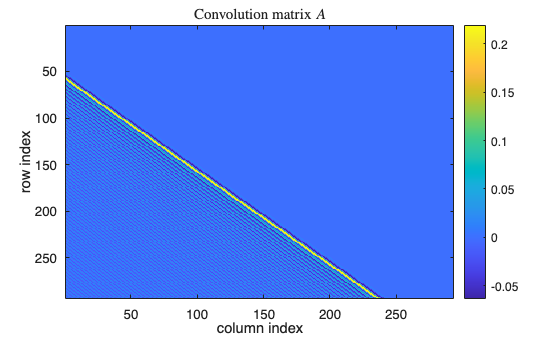

w_data = w(t_cmpG)';

% Constructing convolution matrix
A_row = dt_cmpG*data_green(iZero:-1:1).';
A_col = dt_cmpG*data_green(iZero:end);
A = toeplitz(A_col,A_row);

figure
% spy(F)
imagesc(A)
xlabel('column index')
ylabel('row index')
colorbar
title('Convolution matrix $A$','Interpreter','latex')

% Computing pressure data via matrix multiplication
data_alt_mat = A*w_data;

% Computing pressure data via convolution 
data_alt_conv = dt_cmpG*convDisc(data_green,w_data);

% Interpolating onto coarser receiver time grid
data_alt_mat = interp1(t_cmpG,data_alt_mat,t_rcv,'linear').';
data_alt_conv = interp1(t_cmpG,data_alt_conv,t_rcv,'linear').';

We compare the directly and convolution computed pressure data.

relError_mat = norm(data-data_alt_mat)/norm(data)

relError_mat = 2.5376e-04

relError_conv = norm(data-data_alt_conv)/norm(data)

relError_conv = 2.5376e-04

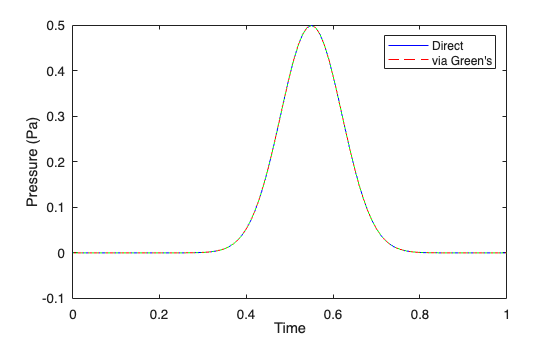


% Plotting both data
figure

plot(t_rcv,data,'-b')
hold on
plot(t_rcv,data_alt_mat,'--r')
plot(t_rcv,data_alt_conv,':g')
hold off

xlabel("Time")
ylabel(P.formattedLabel)
legend("Direct","via Green's")

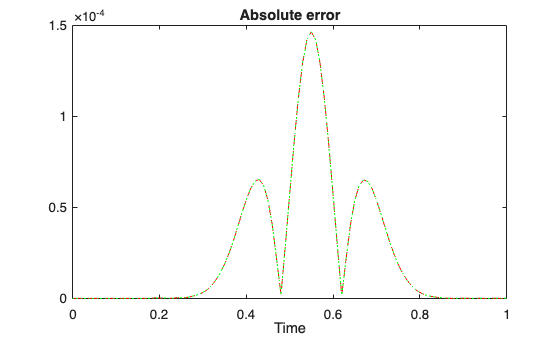

% Plotting error
figure
plot(t_rcv,abs(data-data_alt_mat),'--r')
hold on
plot(t_rcv,abs(data-data_alt_conv),':g')
hold off
xlabel("Time")
title("Absolute error")

## Conclusions

This demo offers a way to validate the computation of a Green's function. 

When computing Green's functions, 

- highly refined grids should be used (in space and time)

- need to take special care when setting up computational time domain (may require zero-padding)

- output time grid should be the same as the computational time grid

- interpolation onto coarser time grid should be done after convolution